Computer Controlled Systems - Control Design Project - Suspension system of a bus

Gyurcsik Máté - U3U9W1

Fegyó Anna - CLPL81

**TASK DESCRIPTION:**

You have a model of a linear time-invariant system, resulting from a real-world engineering problem, with input, output and state variables. 

Your task is the analysis and control of the chosen system, based on the guidelines below. Choosing a suitable initial state, input, control objective (e.g. stabilization, reference tracking), etc. for your model is part of the task. Example parameters were given (or already substituted into the equations) for your model - you can use these for simulations if you want.

All ﬁgures and calculations should be done in MATLAB (hint: there is no need to reinvent the wheel - there are plenty of useful functions and toolboxes for system control and symbolic calculations which you can use. Google them, look at tutorials, try to understand how you can make use of them). As some of the models are quite complicated, there is no need to calculate anything by hand. 

The MATLAB code should be submitted as part of the assignment, so please clean it up when you are ﬁnished and try to make it understandable.

Besides the code, a report should be submitted in PDF format, where you present and explain your work (you can include ﬁgures, formulas, results - anything you feel necessary).

In your work, you should cover the following topics:

**Analysis:**

- State-space model

- Input-output model: transfer function, impulse respponse function

- Response of the system for a given input

- Stability (Lyapunov as well)

- Controllability, Observability

- Discretization

**Control: **(you should choose 3 of the 5 points below)

- PID

- Pole placement, State estimator

- LQR control (continuous time)

- LQR control (discrete time)

- Deadbeat (discrete time)

**OUR TASK: 6. SUSPENSION SYSTEM OF A BUS**

Designing an automotive suspension system is an interesting and challenging control problem. When the suspension system is designed, a 1/4 model (one of the four wheels) is used to simplify the problem to a 1-D multiple spring-damper system. A diagram of this system is shown below. This model is for an active suspension system where an actuator is included that is able to generate the control force u to control the motion of the bus body.

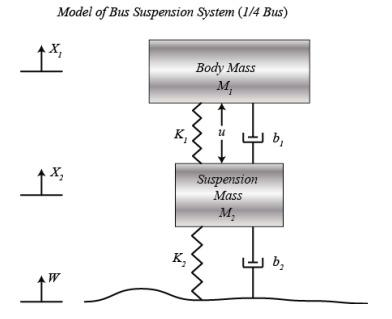

We have the following variables:

syms s
syms u w dw
%syms m1 m2 k1 k2 b1 b2
syms dv1 dv2 
syms v1 v2 x1 x2
syms y

Where w is a disturbance input representing the surface of the road (see figure).

By introducint a variable dv1 = v1 and dv2 = v2, the state-space equation with four state variables, and one output (y = x1 - x2) can be easily derived.

We have the parameter values using SI units:

m1=2500 

m1 = 2500

m2=320 

m2 = 320

k1=80000 

k1 = 80000

k2=500000

k2 = 500000

b1=350 

b1 = 350

b2=15020

b2 = 15020


y=x1-x2

$$y = x_{1}-x_{2}$$

Where m1 is the 1/4 bus body mass, m2 is the suspension mass, k1 is the spring constant of the suspension system, k2 is the spring constant of the wheel and tire, b1 is the damping constant of the suspension system and b2 is the damping constant of the wheel and tire.

The equations for the above model can be written as:

eqvt_1=[m1*dv1==-b1*(v1-v2)-k1*(x1-x2)+u]

$$eqvt\_1 = 2500\,{\mathrm{dv}}_{1}=u-350\,v_{1}+350\,v_{2}-80000\,x_{1}+80000\,x_{2}$$

eqvt_2=[m2*dv2==b1*(v1-v2)+k1*(x1-x2)+b2*(dw-v2)+k2*(w-x2)+u]

$$eqvt\_2 = 320\,{\mathrm{dv}}_{2}=15020\,\mathrm{dw}+u+350\,v_{1}-15370\,v_{2}+500000\,w+80000\,x_{1}-580000\,x_{2}$$

ANALYSIS - STATE-SPACE MODEL

%We express dv1 with the state variables
eqvt_dv1=solve(eqvt_1,dv1)

$$eqvt\_dv1 = \frac{u}{2500}-\frac{7\,v_{1}}{50}+\frac{7\,v_{2}}{50}-32\,x_{1}+32\,x_{2}$$

simplify(eqvt_dv1)

$$ans = \frac{u}{2500}-\frac{7\,v_{1}}{50}+\frac{7\,v_{2}}{50}-32\,x_{1}+32\,x_{2}$$

%We express dv2 with the state variables
eqvt_dv2=solve(eqvt_2,dv2)

$$eqvt\_dv2 = \frac{751\,\mathrm{dw}}{16}+\frac{u}{320}+\frac{35\,v_{1}}{32}-\frac{1537\,v_{2}}{32}+\frac{3125\,w}{2}+250\,x_{1}-\frac{3625\,x_{2}}{2}$$

simplify(eqvt_dv2)

$$ans = \frac{751\,\mathrm{dw}}{16}+\frac{u}{320}+\frac{35\,v_{1}}{32}-\frac{1537\,v_{2}}{32}+\frac{3125\,w}{2}+250\,x_{1}-\frac{3625\,x_{2}}{2}$$

%The derivative of x will be equal to v
eqvt_dx1=v1

$$eqvt\_dx1 = v_{1}$$

eqvt_dx2=v2

$$eqvt\_dx2 = v_{2}$$

First we have to define our A, B, C, D matrices for the state space representation.

syms A B C D

A=[0 0 1 0;
    0 0 0 1;
    -k1/m1 k1/m1 -b1/m1 b1/m1;
    k1/m2 -k2/m2-k1/m2 b1/m2 -b2/m2+b1/m2]

A = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -0.0320    0.0320   -0.0001    0.0001
    0.2500   -1.8125    0.0011   -0.0458


B=[0 0 0;
    0 0 0;
    1/m1 0 0;
    0 b2/m2 b2/m2]

B =          0         0         0
         0         0         0
    0.0004         0         0
         0   46.9375   46.9375


C=[1 -1 0 0]

C =      1    -1     0     0


D=[0 0 0]

D =      0     0     0


Then we have to define our state space model, according to the followings:

- state equation: dv = Ax + Bu

- output equation: y = Cx + Du

ANALYSIS - INPUT-OUTPUT MODEL: TRANSFER FUNCTION, IMPULSE RESPONSE FUNCTION

Our second task is to define the transfer function based on the followings:

- the transfer function H(s) is the Laplace transform of the output Y(s) divided by the Laplace transform of the input U(s).

- the transfer function can be calculated from the state space matrices: $H(s) = C(sI-A)^{-1} B+D$

I_matrix=diag(ones(4,1))

I_matrix =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


H=C*inv(s*I_matrix-A)*B

$$H = \begin{array}{l} \left(\begin{array}{ccc} \frac{32\,s^{2}+1467\,s+58000}{100\,\sigma_{1}}-\frac{7\,s+1600}{20\,\sigma_{1}} & \frac{751\,\left(7\,s+1600\right)}{\sigma_{1}}-\frac{751\,\left(50\,s^{2}+7\,s+1600\right)}{\sigma_{1}} & \frac{751\,\left(7\,s+1600\right)}{\sigma_{1}}-\frac{751\,\left(50\,s^{2}+7\,s+1600\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=800\,s^{4}+36787\,s^{3}+1480612\,s^{2}+1320600\,s+40000000 \end{array}$$

simplify(H)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{2\,\left(4\,s^{2}+179\,s+6250\right)}{25\,\sigma_{2}} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{37550\,s^{2}}{\sigma_{2}}\\ \sigma_{2}=800\,s^{4}+36787\,s^{3}+1480612\,s^{2}+1320600\,s+40000000 \end{array}$$

Then we have to determine the impulse response function which is the inverse Laplace transform of the transfer function.

h=ilaplace(H)

$$h = \begin{array}{l} \left(\begin{array}{ccc} \frac{8\,\sigma_{1}}{25}+500\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{3200\,{\sigma_{2}}^{3}+110361\,{\sigma_{2}}^{2}+2961224\,\sigma_{2}+1320600}\right)+\frac{358\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{2961224\,\sigma_{2}+110361\,{\sigma_{2}}^{2}+3200\,{\sigma_{2}}^{3}+1320600}\right)}{25} & -37550\,\sigma_{1} & -37550\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{3200\,{\sigma_{2}}^{3}+110361\,{\sigma_{2}}^{2}+2961224\,\sigma_{2}+1320600}\\ \sigma_{2}=\mathrm{root}\left({s_{3}}^{4}+\frac{36787\,{s_{3}}^{3}}{800}+\frac{370153\,{s_{3}}^{2}}{200}+\frac{6603\,s_{3}}{4}+50000,s_{3},k\right) \end{array}$$

sys = ss(A,B,C,D)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3     -32      32   -0.14    0.14
   x4     250   -1813   1.094  -45.84
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3  0.0004       0       0
   x4       0   46.94   46.94
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Continuous-time state-space model.



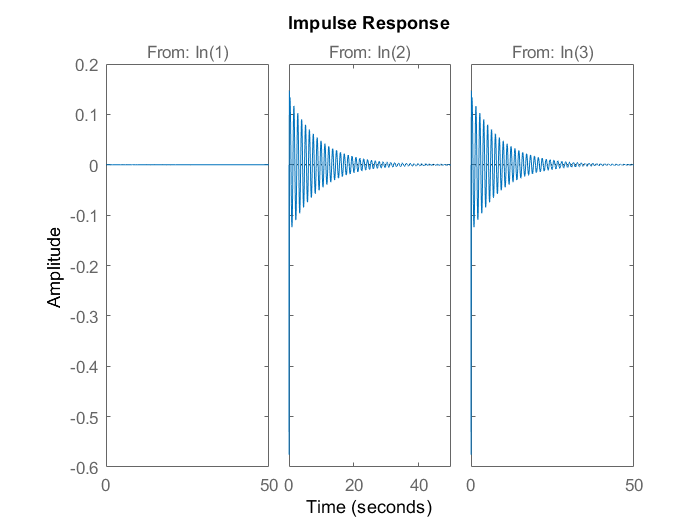

impulse(sys)

ANALYSIS - RESPONSE OF THE SYSTEM FOR A GIVEN INPUT

%initial state
x0 = [0;0;0;0]

x0 =      0
     0
     0
     0


%time & input
Tf = 10;
Ts = 0.1;
[uSq,t] = gensig("sine",4,Tf,Ts);
[uP,~] = gensig("sine",3,Tf,Ts);
[uV,~] = gensig("sine",4,Tf,Ts);
u = [uSq uP uV];
%response
y=lsim(sys,u,t)

y =          0
   -0.0067
   -0.0138
   -0.0164
   -0.0137
   -0.0063
    0.0040
    0.0145
    0.0226
    0.0261


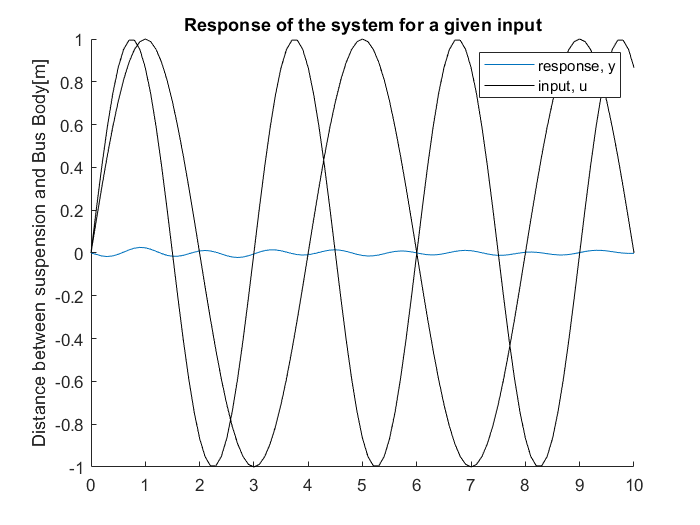

%plotting
figure
hold on
plot(t,y)
plot(t,u,'k')
title('Response of the system for a given input')
legend('response, y','input, u')
ylabel('Distance between suspension and Bus Body[m]')
hold off

ANALYSIS - STABILITY (LYAPUNOV AS WELL)

First we want to decide the stability considering the poles of the transfer function. We need their real part to be negative in order to determine stability.

disp("The system is stable:")

The system is stable:


isstable(sys)

ans = logical
   1


Then we can check the stability considering the eigenvalues of matrix A. We need their real part to be negative in order to determine stability.

e = eig (A)

e =  -22.8847 +35.9120i
 -22.8847 -35.9120i
  -0.1072 + 5.2499i
  -0.1072 - 5.2499i


isAlways(e<zeros(4,1))

ans = 4×1 logical array
   1
   1
   1
   1


We got asymptotic stability that implies BIBO stability so this part of the stability is proven.

Now we have to consider Lyapunov stability as well. Lyapunov stability theorem has three main conditions:

- V > 0, if $x \ne x^*, V(x^*)=0
$

- V continuously differentiable

- V non-increasing, $V'(x) = grad(V)x'\leq0$

%we need a lyapunov function
Q=[1 0 0 0;0 1 0 0; 0 0 1 0; 0 0 0 1]

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



P=lyap(A,Q)

P =     2.4570    0.3368   -0.5000    0.2567
    0.3368    0.0707   -0.2567   -0.5000
   -0.5000   -0.2567   67.7386    8.5482
    0.2567   -0.5000    8.5482   21.3828


disp("This is how lyupanov stable they are, if 0 than not")

This is how lyupanov stable they are, if 0 than not


A*P+P*transpose(A)==Q

ans = 4×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


ANALYSIS - CONTROLLABILITY, OBSERVABILITY

First we need to check controllability. Controllability means that we want to influence the state with appropriate input, knowing the model (setting the initial condition).

Our model is controllable if the controllability matrix: $C_n=[\matrix{B & AB & A^2B & ... & A^{n-1}B}]
$ is full-rank.

cm = ctrb(A,B)

cm = 	1.0e+06 *

         0         0         0    0.0000         0         0   -0.0000    0.0000    0.0000   -0.0000    0.0012    0.0012
         0         0         0         0    0.0000    0.0000    0.0000   -0.0022   -0.0022    0.0000    0.0136    0.0136
    0.0000         0         0   -0.0000    0.0000    0.0000   -0.0000    0.0012    0.0012    0.0000   -0.0673   -0.0673
         0    0.0000    0.0000    0.0000   -0.0022   -0.0022    0.0000    0.0136    0.0136   -0.0000    3.2806    3.2806


r = rank(cm)

r = 4

controllable = logical(r==length(cm))

controllable = logical
   0


c_subspace = colspace(sym(cm))

$$c\_subspace = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Then we need to check observability. Observability means that we need state information from the measurements(output), knowing the model(determining the initial condition).

om = obsv(A,C)

om = 	1.0e+04 *

    0.0001   -0.0001         0         0
         0         0    0.0001   -0.0001
   -0.0282    0.1845   -0.0001    0.0046
    1.1535   -8.3385   -0.0232   -0.0264


r = rank(om)

r = 4

observabl = logical(r==length(om))

observabl = logical
   1


% uo_subspace = null(sym(om))

ANALYSIS - DISCRETIZATION

Discretization of a linear state space model is the transformation of continuous differential equations into discrete difference equations, suitable for numerical computing.

For transforming a continuous function into a piecewise constant signal we use zero order hold sampling in which the key point is that the sampled signal is kept constant between two sampling instants.

We need to use the following equations:

- state equation: x(k+1) = $\Phi$x(k) + $\Gamma$u(k)

- output equation: y(k) = Cx(k) + Du(k)

sysd=c2d(sys,Ts)


sysd =
 
  A = 
              x1         x2         x3         x4
   x1     0.8571     0.0656    0.09446   0.001328
   x2     0.1428    -0.1123    0.01038  -0.001097
   x3     -2.691     0.6152     0.8453    0.01793
   x4    -0.6064      2.321     0.1401   -0.06054
 
  B = 
              u1         u2         u3
   x1  1.941e-06   0.002323   0.002323
   x2  1.547e-07    0.02913    0.02913
   x3  3.778e-05    0.06235    0.06235
   x4  4.151e-06    -0.0515    -0.0515
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



[dig_A, dig_B, dig_C, dig_D]=ssdata(sys)

dig_A = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -0.0320    0.0320   -0.0001    0.0001
    0.2500   -1.8125    0.0011   -0.0458


dig_B =          0         0         0
         0         0         0
    0.0004         0         0
         0   46.9375   46.9375


dig_C =      1    -1     0     0


dig_D =      0     0     0


CONTROL - POLE PLACEMENT, STATE ESTIMATOR

Full state feedback (FSF) or pole placement is a method employed in feedback control system theory to place the closed-loop poles of a plant (system) in pre-determined locations in the s-plane. Placing poles is desirable because the location of the poles corresponds directly to the eigenvalues of the system, which control the characteristics and stability of the response of the system. The system must be considered controllable in order to implement this method. We checked this before so we can implement the method.

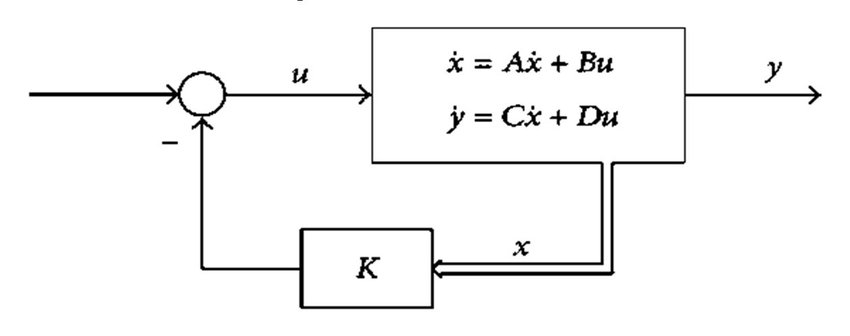

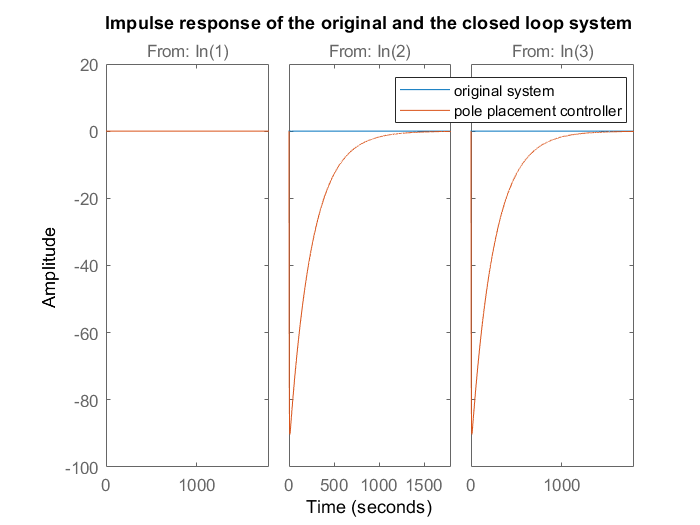

%first we need to define the poles
p = [-0.004 -0.5 -1.23 -5.0];
%K_pp is the state-feedback gain matrix that we want to calculate
K_pp = place (A,B,p);
%closed loop system
sys_pp = ss(A-B*K_pp,B,C,D);
%then we need the impulse response of the original and the closed loop
%system
impulse(sys,sys_pp);
%impulse response
legend('original system','pole placement controller');
title('Impulse response of the original and the closed loop system');

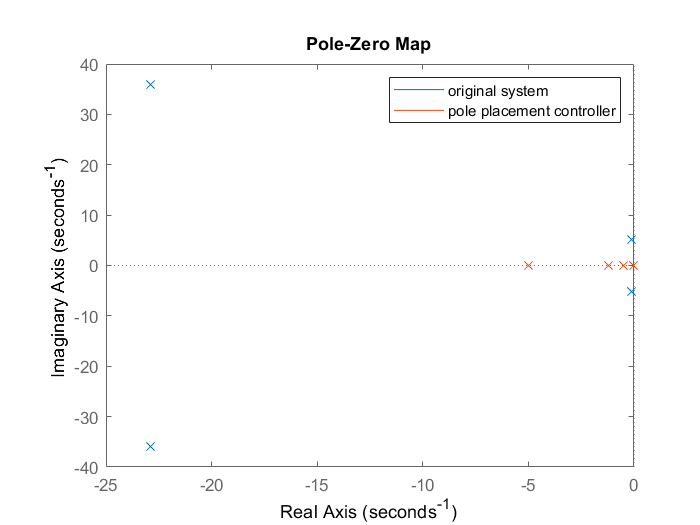

%pole-zero map
pzmap(sys,sys_pp)
legend('original system','pole placement controller');

In control theory, a state observer or state estimator is a system that provides an estimate of the internal state of a given real system, from measurements of the input and output of the real system. 

 The system must be considered observable in order to implement this method. We checked this before so we can implement the method. It is required that the system should be asymptotically stable.

%first we need to define the poles
p = [-0.004 -0.5 -1.23 -5.0];
%state observer transposed
L_so_transp = place (A',C',p);
L_so = L_so_transp'

L_so =    -0.1380
   39.1117
  -26.5050
   10.1174


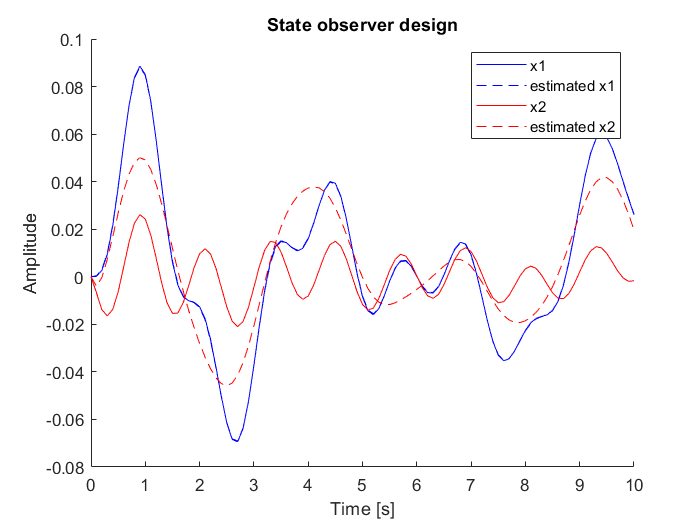


%closed loop system
sys_so = ss(A-L_so*C,[B, L_so], eye(4),zeros(4,4));

%estimated output
y_est = lsim(sys_so,[u,y],t); 

sys2 = ss(A,B,[1 0 0 0],D);
y1 = lsim(sys2,u,t,x0);

%plotting the states
figure;
hold on;
plot(t,y1,'b');
plot(t,y_est(:,1),'b--');
plot(t,y,'r');
plot(t,y_est(:,2),'r--');
legend('x1','estimated x1', 'x2','estimated x2');
title('State observer design');
xlabel('Time [s]');
ylabel('Amplitude');
hold off;

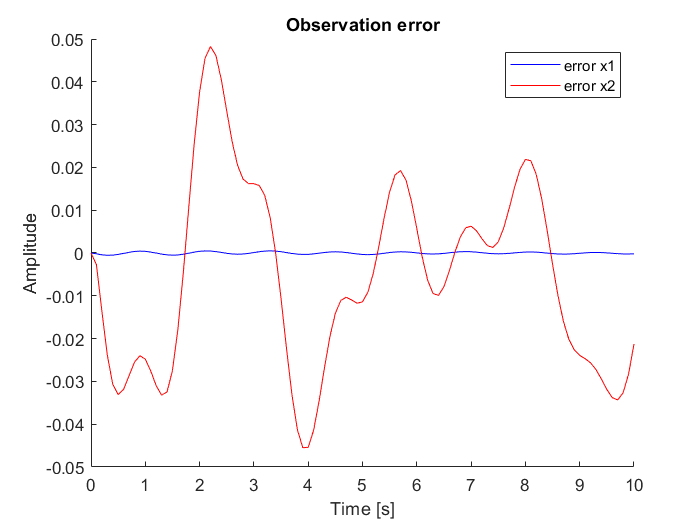


%plotting the error of states
figure;
hold on;
plot(t,y1-y_est(:,1),'b');
plot(t,y-y_est(:,2),'r');
legend('error x1','error x2');
title('Observation error');
xlabel('Time [s]');
ylabel('Amplitude');
hold off;

CONTROL - LQR  Continuos

**Linear-quadratic regulator**

An LQR system is a full state feedback controller. It's structure is similar to pole placement the difference is the K which we use to drive the feedback loop, from the state vector. In pole placement we find our K(L_so) to place the pole in the desired place, but here we use our  K(C_lqr / D_lqr) to optimise our system's characteristics. We use weights to optimise the inputs(R) and the states(Q) more independently. 

%Control Law
Q=[1 0 0 0;    
    0 1 0 0;
    0 0 1 0;
    0 0 0 1]   

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R=1

R = 1

N=[0 0 0; 0 0 0;0 0 0 ; 0 0 0]

N =      0     0     0
     0     0     0
     0     0     0
     0     0     0


[C_lqr,S,e]=lqr(sys,Q,R,N)

C_lqr =    -0.0000    0.0003    0.0003    0.0000
   -0.6691    0.6991    0.5432    0.3806
   -0.6691    0.6991    0.5432    0.3806


S =    21.0227   -2.8039   -0.1097   -0.0143
   -2.8039   15.4218    0.8433    0.0149
   -0.1097    0.8433    0.7701    0.0116
   -0.0143    0.0149    0.0116    0.0081


e =   -0.6073 + 5.2357i
  -0.6073 - 5.2357i
 -40.2470 +13.5336i
 -40.2470 -13.5336i



c_lqr_sys=ss(A-B*C_lqr,B,C,D)


c_lqr_sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3     -32      32   -0.14    0.14
   x4   312.8   -1878   -49.9  -81.57
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3  0.0004       0       0
   x4       0   46.94   46.94
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Continuous-time state-space model.




x0=[1; 2; 1; 1]

x0 =      1
     2
     1
     1


t=0:0.005:30;
[y,t,x]= initial(c_lqr_sys,x0,t)

y =    -1.0000
   -0.9605
   -0.8615
   -0.7262
   -0.5716
   -0.4097
   -0.2490
   -0.0949
    0.0489
    0.1806


t =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


x =     1.0000    2.0000    1.0000    1.0000
    1.0054    1.9659    1.1523  -13.5979
    1.0115    1.8730    1.2848  -22.8062
    1.0182    1.7444    1.3932  -28.0707
    1.0254    1.5970    1.4756  -30.5043
    1.0329    1.4426    1.5315  -30.9558
    1.0407    1.2896    1.5616  -30.0659
    1.0485    1.1434    1.5674  -28.3128
    1.0563    1.0074    1.5508  -26.0481
    1.0640    0.8834    1.5139  -23.5259


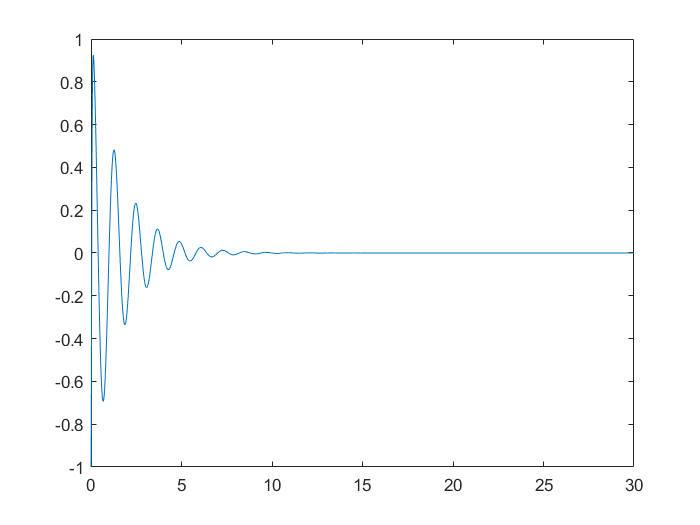


plot(t,y)

CONTROL - LQR digital

Q=[1 0 0 0;0 1 0 0; 0 0 1 0; 0 0 0 1]

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R=1

R = 1

N=[0 0 0; 0 0 0;0 0 0 ; 0 0 0]

N =      0     0     0
     0     0     0
     0     0     0
     0     0     0


[D_lqr,D_S,D_e]=dlqr(dig_A,dig_B,Q,R,N)

D_lqr =    -7.1389    7.1390   -0.2266    0.2330
    3.0036  -19.6480    0.0128   -0.4895
    3.0036  -19.6480    0.0128   -0.4895


D_S = 	1.0e+05 *

    5.7113   -5.7123    0.1813   -0.1864
   -5.7123    5.7188   -0.1813    0.1866
    0.1813   -0.1813    5.7067   -5.7077
   -0.1864    0.1866   -5.7077    5.7143


D_e =   -0.0038 + 0.1900i
  -0.0038 - 0.1900i
  -0.0126 + 0.0198i
  -0.0126 - 0.0198i


D_lqr_sys=ss(dig_A-dig_B*D_lqr,dig_B,dig_C,dig_D)


D_lqr_sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3      -32       32  -0.1399   0.1399
   x4   -31.96    31.96  -0.1071   0.1071
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3  0.0004       0       0
   x4       0   46.94   46.94
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Continuous-time state-space model.

